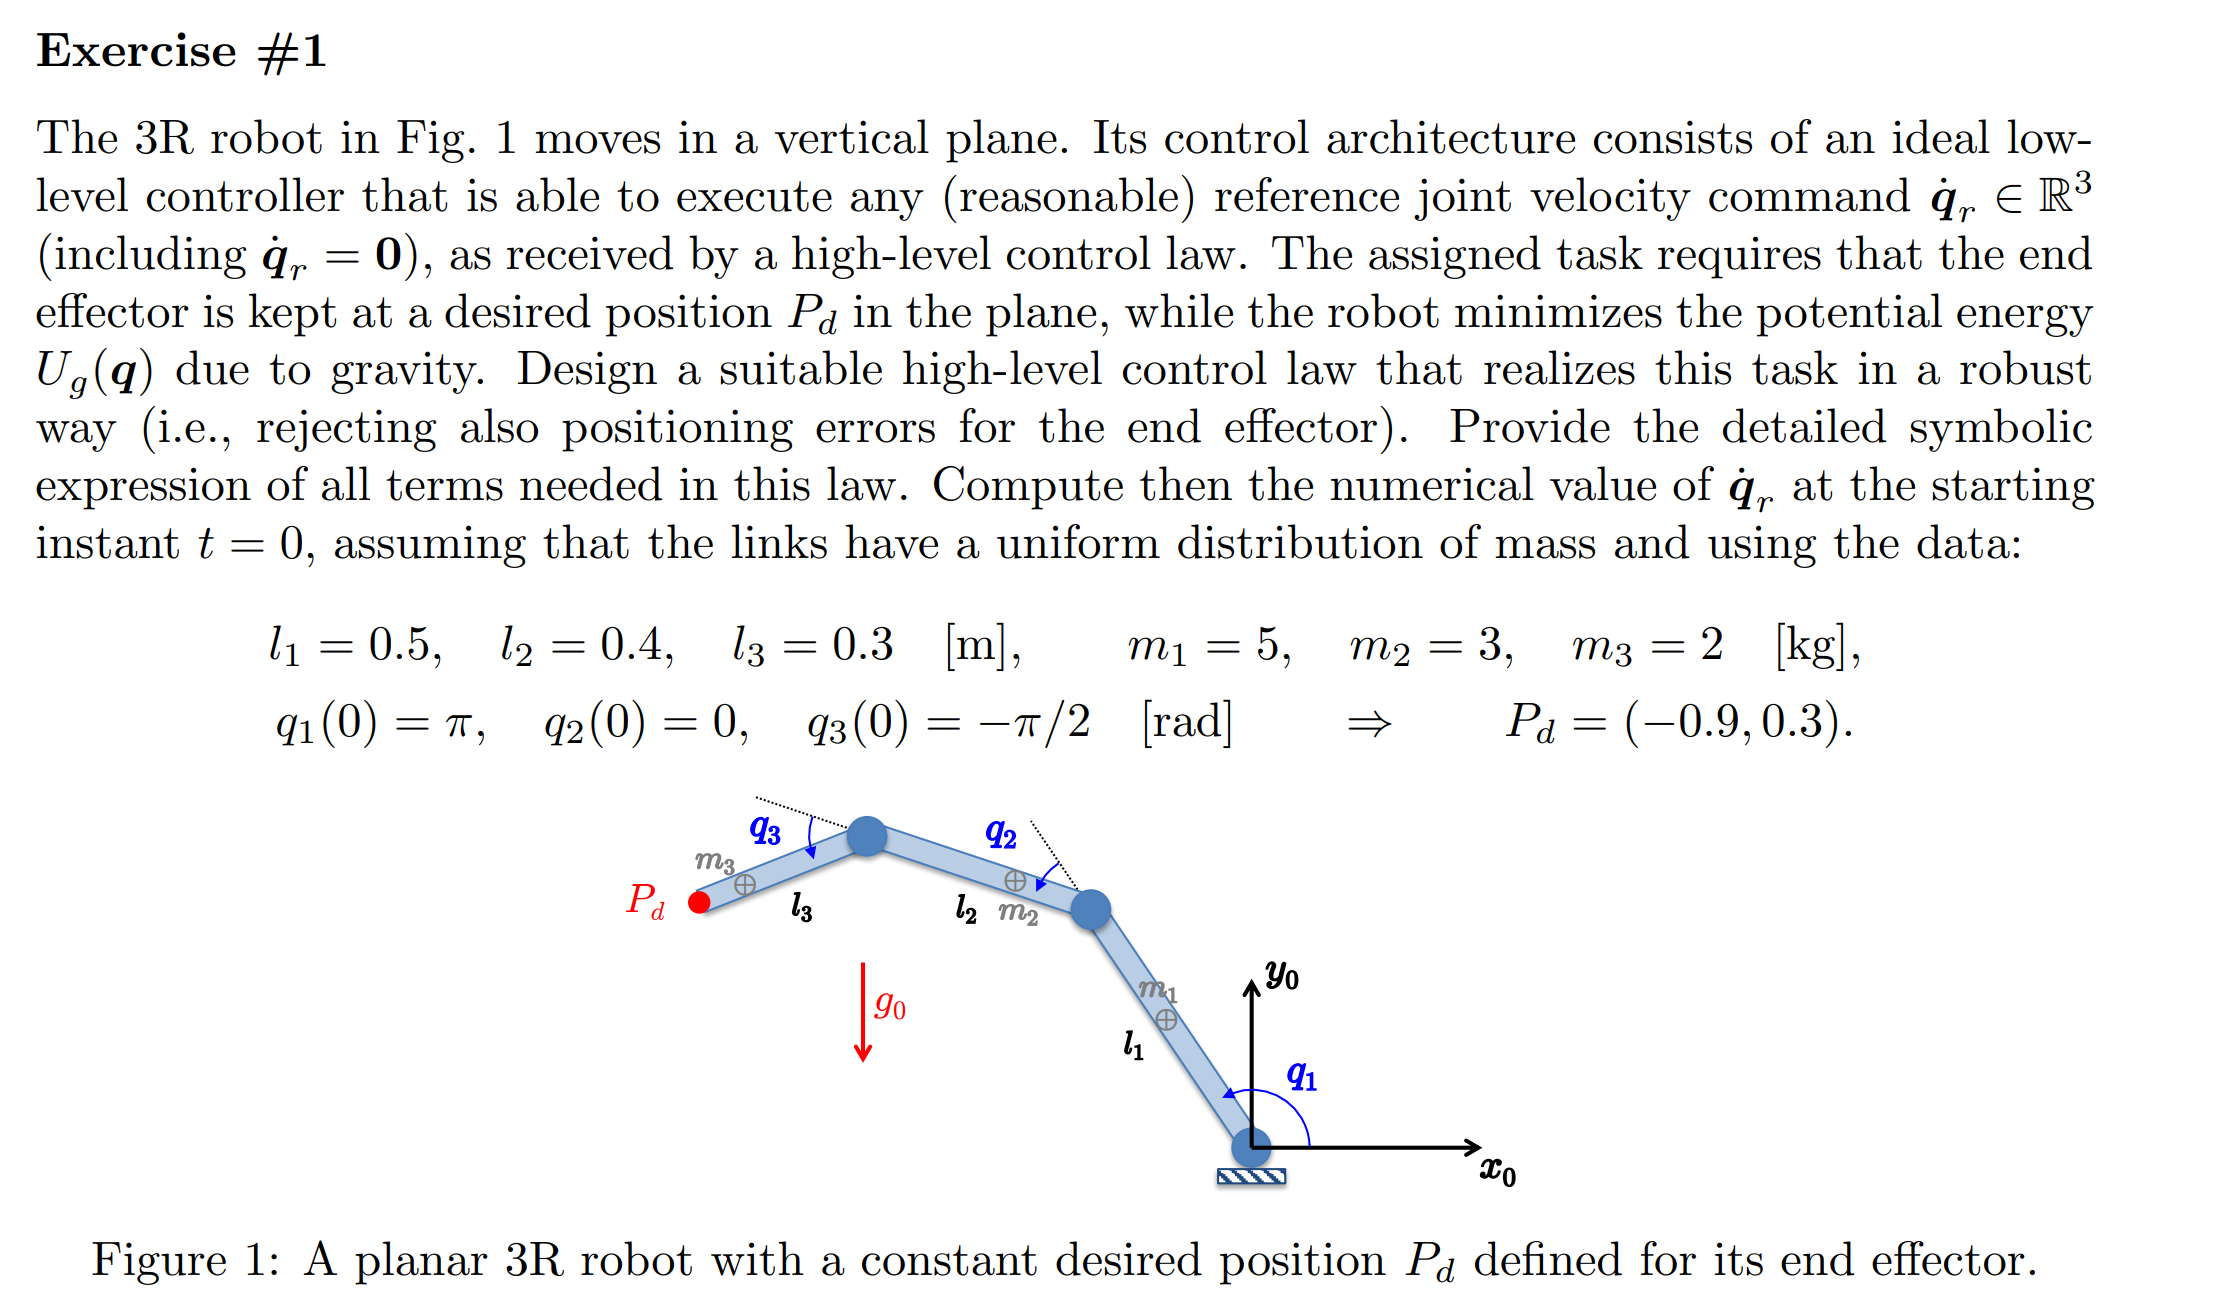

syms q1 q2 q3 m_1 m_2 m_3 l_1 l_2 l_3 d_1 d_2 d_3 g0 real

U1 = m_1*g0*(d_1*sin(q1))

$$U1 = d_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)$$

U2 = m_2*g0*(l_1*sin(q1)+d_2*sin(q1+q2))

$$U2 = g_{0}\,m_{2}\,\left(d_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)$$

U3 = m_3*g0*(l_1*sin(q1)+l_2*sin(q1+q2)+d_3*sin(q1+q2+q3))

$$U3 = g_{0}\,m_{3}\,\left(l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)+d_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\right)$$


U = [U1+U2+U3]

$$U = g_{0}\,m_{3}\,\left(l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)+d_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\right)+g_{0}\,m_{2}\,\left(d_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)+d_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)$$


g_q = simplify([diff(U,q1); diff(U,q2); diff(U,q3)])

$$g\_q = \begin{array}{l} \left(\begin{array}{c} g_{0}\,m_{3}\,\left(\sigma_{2}+l_{1}\,\cos\left(q_{1}\right)+\sigma_{1}\right)+g_{0}\,m_{2}\,\left(d_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\right)+d_{1}\,g_{0}\,m_{1}\,\cos\left(q_{1}\right)\\ g_{0}\,m_{3}\,\left(\sigma_{2}+\sigma_{1}\right)+d_{2}\,g_{0}\,m_{2}\,\cos\left(q_{1}+q_{2}\right)\\ d_{3}\,g_{0}\,m_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=d_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{2}=l_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}$$


p = [l_1*cos(q1)+l_2*cos(q1+q2)+l_3*cos(q1+q2+q3);
     l_1*sin(q1)+l_2*sin(q1+q2)+l_3*sin(q1+q2+q3);];
J = jacobian(p,[q1,q2,q3])

$$J = \begin{array}{l} \left(\begin{array}{ccc} -l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right)-\sigma_{1} & -l_{2}\,\sin\left(q_{1}+q_{2}\right)-\sigma_{1} & -\sigma_{1}\\ l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+\sigma_{2} & l_{2}\,\cos\left(q_{1}+q_{2}\right)+\sigma_{2} & \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{2}=l_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$


g_q_dot = jacobian(g_q,[q1,q2,q3])

$$g\_q\_dot = \begin{array}{l} \left(\begin{array}{ccc} -g_{0}\,m_{3}\,\left(l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)+d_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\right)-g_{0}\,m_{2}\,\left(d_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)-d_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right) & \sigma_{1} & \sigma_{2}\\ \sigma_{1} & \sigma_{1} & \sigma_{2}\\ \sigma_{2} & \sigma_{2} & \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-g_{0}\,m_{3}\,\left(l_{2}\,\sin\left(q_{1}+q_{2}\right)+d_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\right)-d_{2}\,g_{0}\,m_{2}\,\sin\left(q_{1}+q_{2}\right)\\ \sigma_{2}=-d_{3}\,g_{0}\,m_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$


% Pseudoinversa
J_pinv = simplify(pinv(J));

% Identità
I = eye(3);

% Delta x (task incrementale desiderato)
syms dx dy real
Delta_x = [dx; dy];

% Soluzione finale
%Delta_q = simplify(J_pinv * Delta_x - (I - J_pinv * J) * g_q);
%disp('Delta_q that minimizes potential energy and performs the task:')
%disp(Delta_q)

% Sostituzioni numeriche
% values = {
%     l_1, 1; l_2, 1; l_3, 1;
%     d_1, 0.5; d_2, 0.5; d_3, 0.5;
%     m_1, 1; m_2, 1; m_3, 1;
%     g0, 9.81;
%     q1, pi/4; q2, pi/6; q3, -pi/6;
%     dx, 0.1; dy, -0.05
% };
% 
% Delta_q_num = double(subs(Delta_q, values));
% 
% disp('Delta_q (valutato numericamente):');
% disp(Delta_q_num);

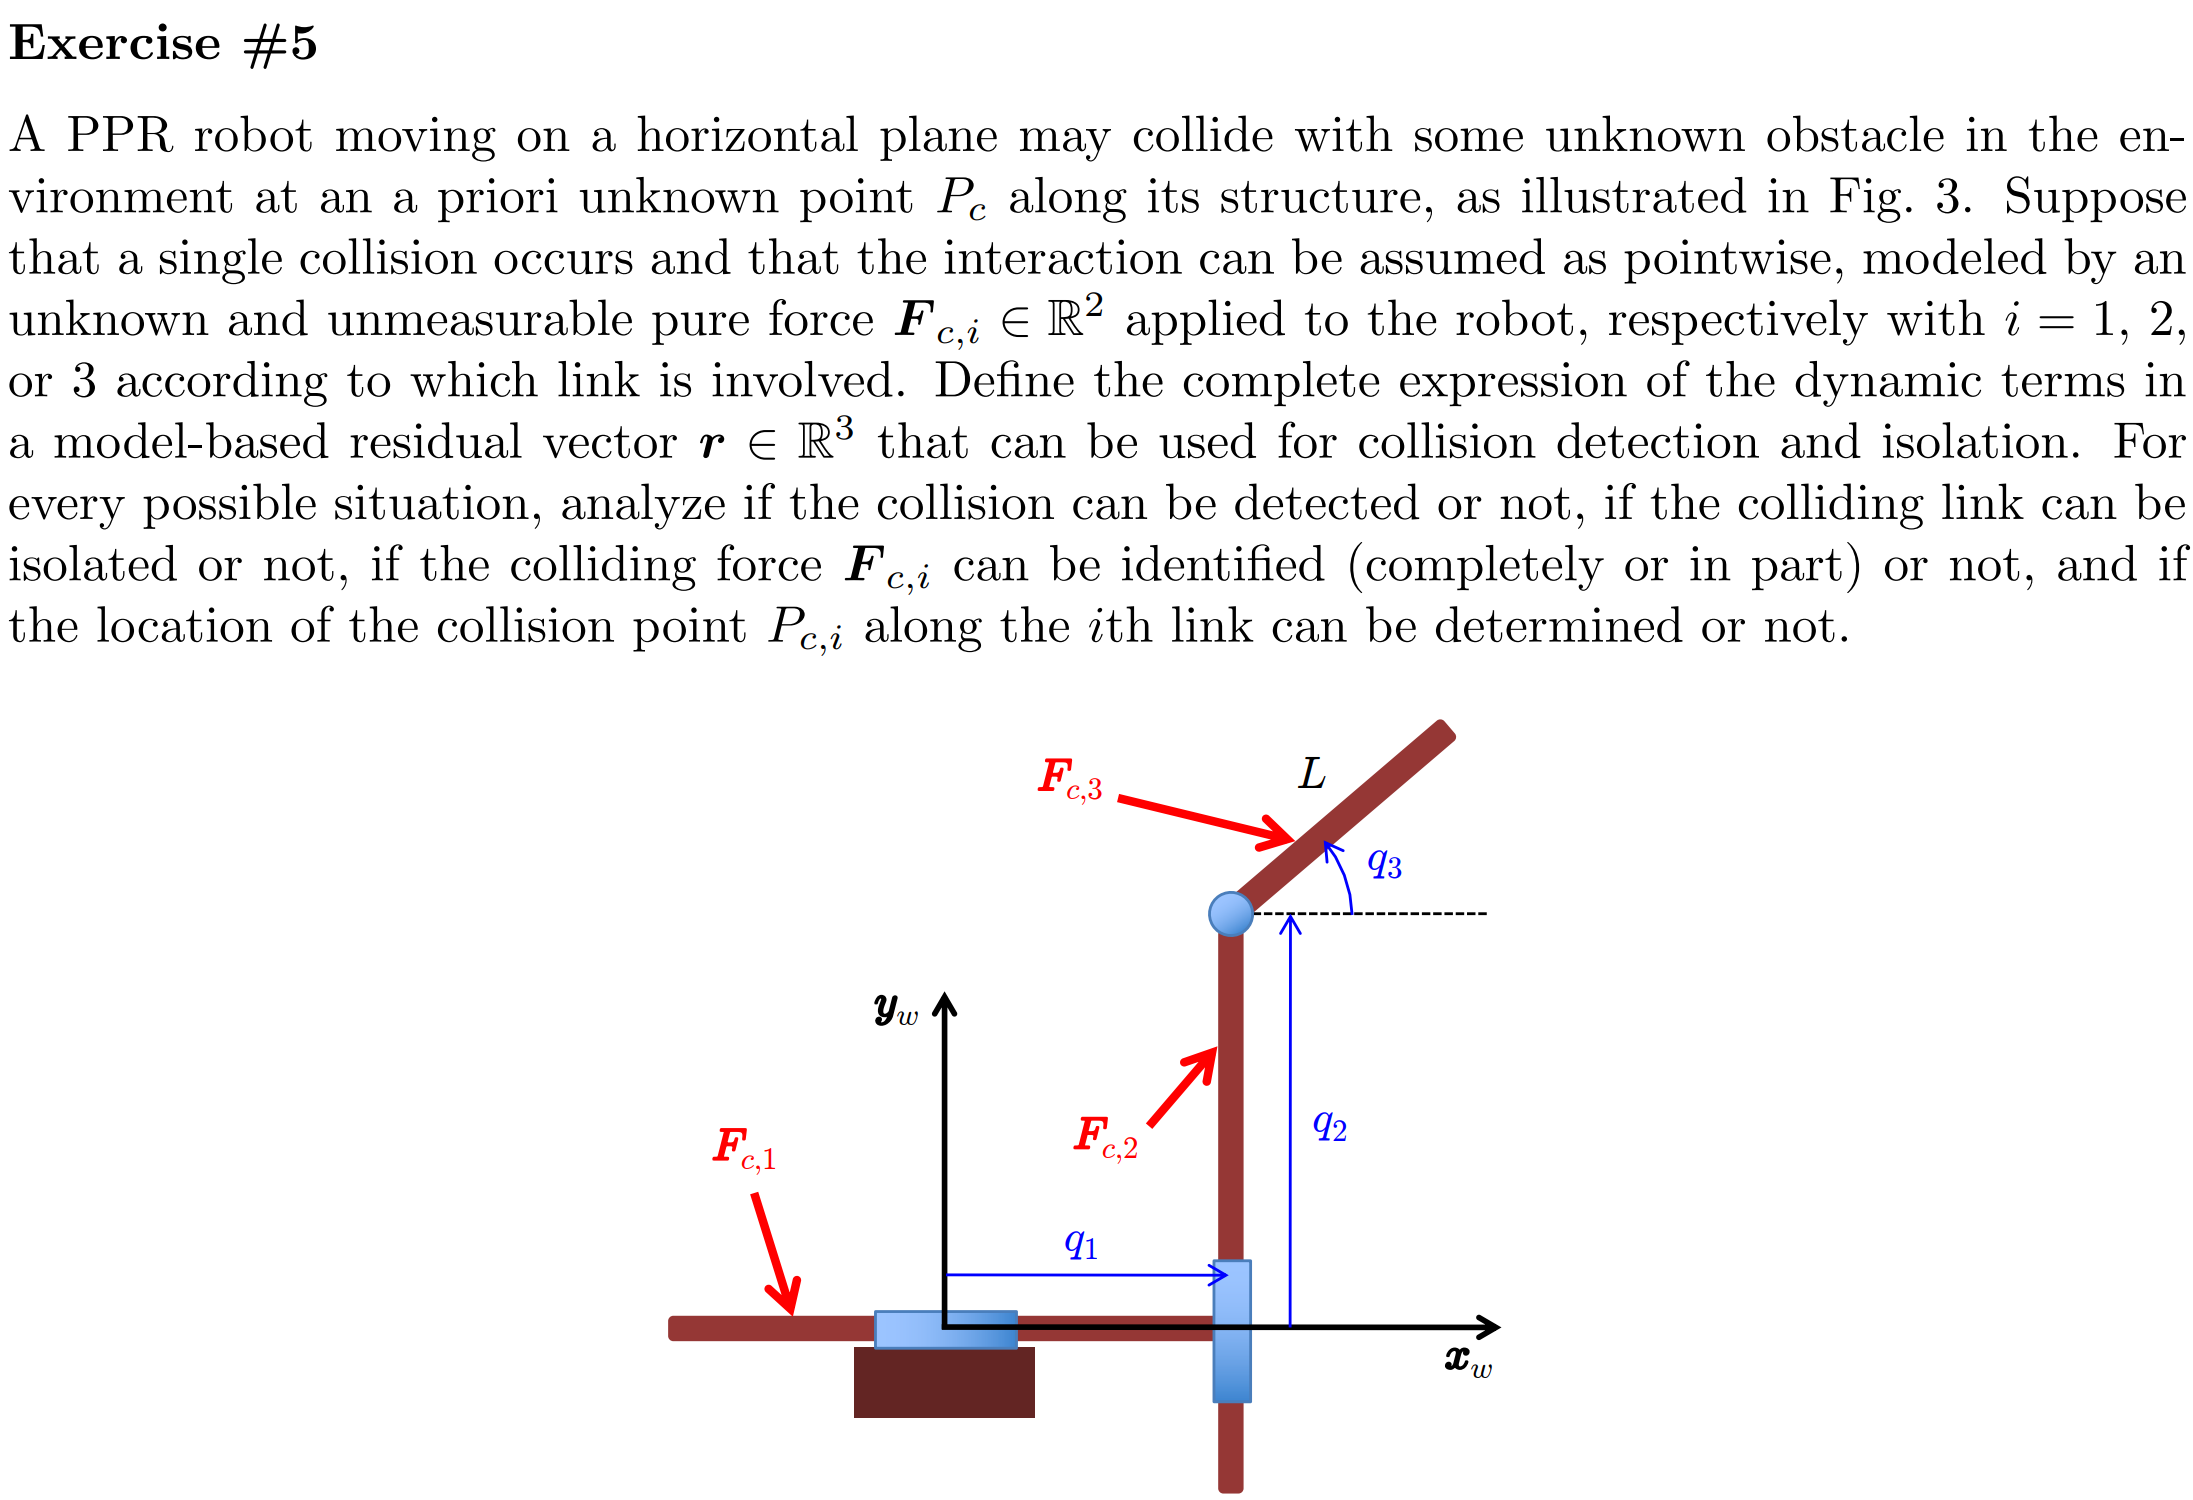

syms q1 q2 q3 q_dot_1 q_dot_2 q_dot_3 m_1 m_2 m_3 L d_3 I_3 real

T1 = 0.5*m_1*q_dot_1^2

$$T1 = \frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

T2 = 0.5*m_2*(q_dot_1^2+q_dot_2^2)

$$T2 = \frac{m_{2}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}$$


x3 = q1+d_3*cos(q3);
y3 = q2+d_3*sin(q3);
vx3 = diff(x3,q1)*q_dot_1+diff(x3,q2)*q_dot_2+diff(x3,q3)*q_dot_3

$$vx3 = {\dot{q}}_{1}-d_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)$$

vy3 = diff(y3,q1)*q_dot_1+diff(y3,q2)*q_dot_2+diff(y3,q3)*q_dot_3

$$vy3 = {\dot{q}}_{2}+d_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)$$


T3 = 0.5*m_3*[vx3 vy3]*[vx3; vy3;]+0.5*I_3*q_dot_3^2

$$T3 = \frac{m_{3}\,{\left({\dot{q}}_{2}+d_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\right)}^{2}}{2}+\frac{m_{3}\,{\left({\dot{q}}_{1}-d_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\right)}^{2}}{2}+\frac{I_{3}\,{{\dot{q}}_{3}}^{2}}{2}$$


T = T1+T2+T3

$$T = \frac{m_{3}\,{\left({\dot{q}}_{2}+d_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\right)}^{2}}{2}+\frac{m_{3}\,{\left({\dot{q}}_{1}-d_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\right)}^{2}}{2}+\frac{I_{3}\,{{\dot{q}}_{3}}^{2}}{2}+\frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{m_{2}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}$$


% Inertia Matrix
M11 = diff(diff(T, q_dot_1), q_dot_1);
M12 = diff(diff(T, q_dot_1), q_dot_2);
M13 = diff(diff(T, q_dot_1), q_dot_3);

M21 = diff(diff(T, q_dot_2), q_dot_1);
M22 = diff(diff(T, q_dot_2), q_dot_2);
M23 = diff(diff(T, q_dot_2), q_dot_3);

M31 = diff(diff(T, q_dot_3), q_dot_1);
M32 = diff(diff(T, q_dot_3), q_dot_2);
M33 = diff(diff(T, q_dot_3), q_dot_3);

M = simplify([M11, M12, M13; M21, M22, M23; M31, M32, M33])

$$M = \left(\begin{array}{ccc} m_{1}+m_{2}+m_{3} & 0 & -d_{3}\,m_{3}\,\sin\left(q_{3}\right)\\ 0 & m_{2}+m_{3} & d_{3}\,m_{3}\,\cos\left(q_{3}\right)\\ -d_{3}\,m_{3}\,\sin\left(q_{3}\right) & d_{3}\,m_{3}\,\cos\left(q_{3}\right) & m_{3}\,{d_{3}}^{2}+I_{3} \end{array}\right)$$


% Coriolis and Centrifugal terms
q  = [q1; q2; q3;];
dq = [q_dot_1; q_dot_2; q_dot_3;];
C = sym(zeros(3,3));

for i = 1:3
    for j = 1:3
        tmp = 0;
        for k = 1:3
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

c_vec = simplify(C * dq);

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{ccc} 0 & 0 & -d_{3}\,m_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\\ 0 & 0 & -d_{3}\,m_{3}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\\ 0 & 0 & 0 \end{array}\right)$$

disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} -d_{3}\,m_{3}\,{{\dot{q}}_{3}}^{2}\,\cos\left(q_{3}\right)\\ -d_{3}\,m_{3}\,{{\dot{q}}_{3}}^{2}\,\sin\left(q_{3}\right)\\ 0 \end{array}\right)$$